Create database!

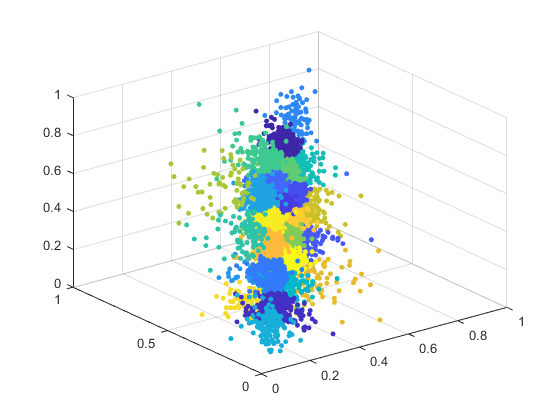

Database has been created containing:200 images


numberOfCluster = 25;
clusterSize = 8; 
tinyImgSize = 24; 

% The resulting number of images comes from numberOfCluster * cluterSize
% 25 * 4 = 100 images for example

[smallDatabase, meanSmallDB] = filtering(numberOfCluster,clusterSize,tinyImgSize);

Create reconstructed image from smaller images that comes from the database

% Name of the file (Must be of type jpg)
fileName = '.jpg';
% The size for each "cell" that goes through the image. Recommended size = 8
cellSize = 8;
% Number of 'good-matches' to use SSIM on. Higher = better quality (but also more compute heavy)
n = 3;

% call function to create image
[imgOUT, imgSSIM, imgSNR, imgDE] = image_rec_v1(fileName, smallDatabase, meanSmallDB, cellSize, n);

Image dimensions are not divisible by:8
The size of the image has been changed to:1168x728
Some information from the original image has therefore been lost
Image is processing...5%
Image is processing...10%
Image is processing...15%
Image is processing...20%
Image is processing...25%
Image is processing...30%
Image is processing...35%
Image is processing...40%
Image is processing...45%
Image is processing...50%
Image is processing...55%
Image is processing...60%
Image is processing...65%
Image is processing...70%
Image is processing...75%
Image is processing...80%
Image is processing...85%
Image is processing...90%
Image is processing...95%
Image is processing...100%
Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...
SSIM:0.000061
SNR:0.063495
DELTA E

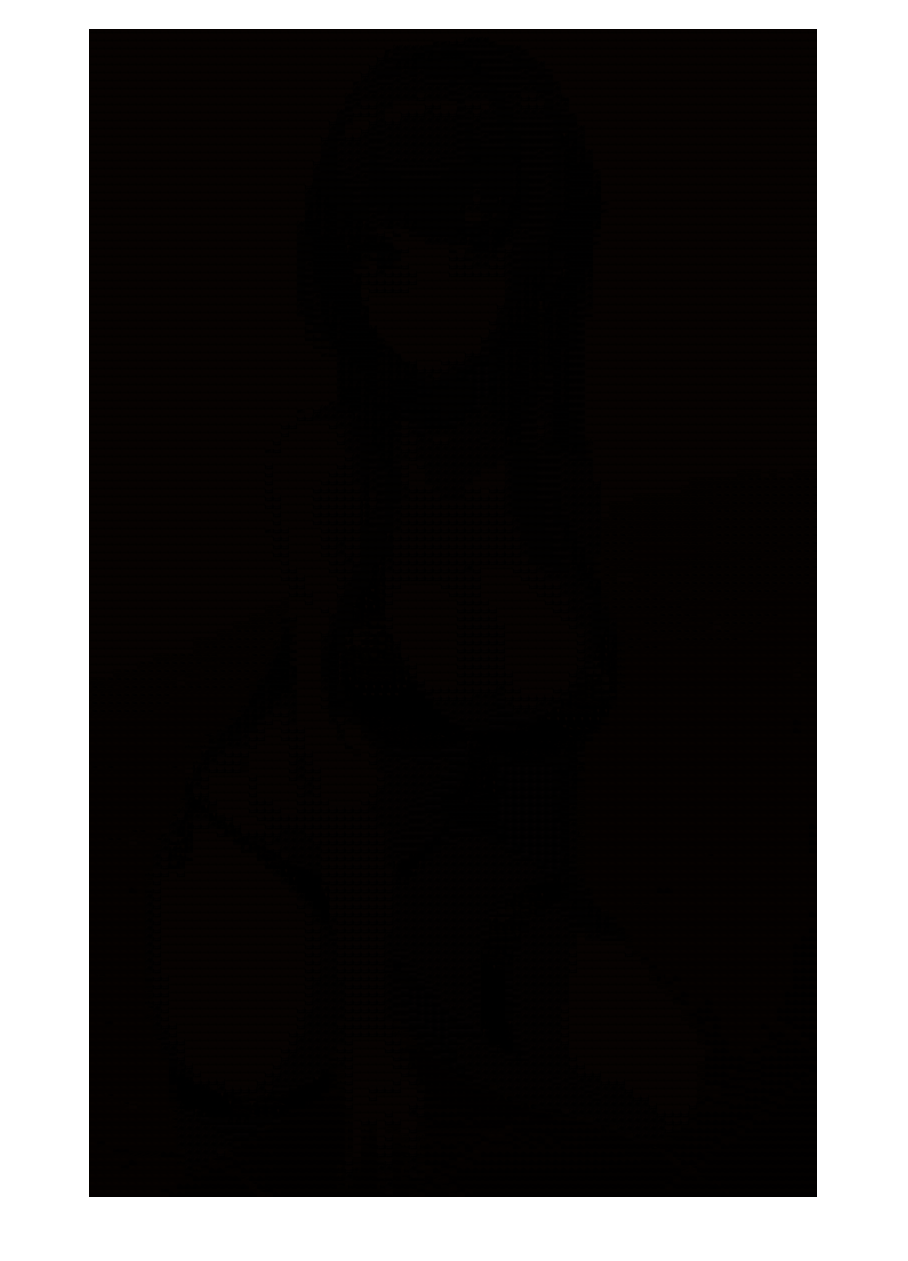


% show the final image
imshow(lab2rgb(imgOUT))